# Shortest Vector Problem (SVP)

Como se explico en el paper

format long
x = 0:0.1:100;
y = @(x) -(0.5) * log(1 - cos(x)) - 0.0999;

plot(x, y(x), "b") % Note the use of y(x) here
%title('c = -1/2 log(1 - cos(x)) - 0.0999')
%xlabel('x')
%ylabel('y') 
%text(3, -0.5, '$c = -\frac{1}{2} \log(1 - \cos(x)) - 0.0999$', 'Interpreter', 'latex')
hold on

xx = 1:3:63;
yy = y(xx);


Spline Natural

spline = splinenatural(xx,yy);

Interpolación Lagrange

coeficientes = lagrange(xx,yy)

coeficientes = 1.0e+05 *

   0.000000000000000  -0.000000000000000   0.000000000000000  -0.000000000000000   0.000000000000000  -0.000000000000000   0.000000000000027  -0.000000000001486   0.000000000064041  -0.000000002197498   0.000000060195324  -0.000001314397326   0.000022749765796  -0.000308940405723   0.003239977839497  -0.025634454559290   0.147820934488895  -0.589405183058063   1.490735206705878  -2.035455883643812   1.008989736134702



pol_lagrange = polyval(coeficientes, xx)

pol_lagrange =    0.288693096197676  -0.351390553085366   0.601113236829406  -0.404530487110605   1.090085328061832  -0.435776410304243   2.141773159994045  -0.446465711371275   2.266722426313208  -0.436997945333133   1.131760084303096  -0.405363749159733   0.628720425040228  -0.340390668396140   0.362199869647156  -0.166523287683958   0.344447145791491   0.519234238745412   1.687404346332187   2.462349045294104   5.767606794601306


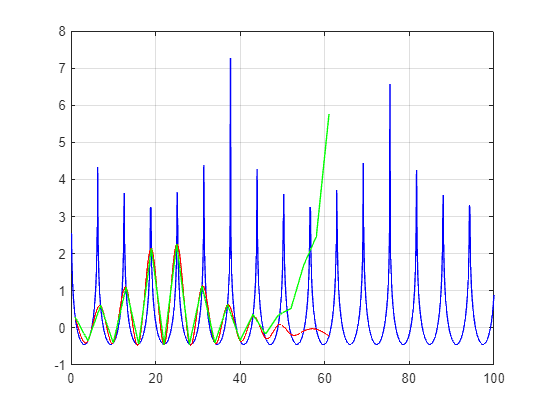

%hold off

plot(xx, pol_lagrange, "g");
%hold on
%plot(xx, pol_lagrange, 'ob', 'MarkerSize', 4);
hold off



%pol_y = polyval(coeficientes, xx)

%plot(xx, pol_y, "g")

Newton 

Minimos Cuadrados

Función de Spline

function S=splinenatural(X,Y)
    N = length(X)-1;
    H = diff(X);
    E = diff(Y)./H;
    diagprinc = 2*(H(1:N-1)+H(2:N));
    diagsupinf = H(2:N-1);
    g0 = 0; gn = 0;
    A = diag(diagprinc)+diag(diagsupinf,1)+diag(diagsupinf,-1);
    b = 6*diff(E');
    g = A\b;
    g = [g0 g' gn];

    for i = 1:N
        S(i,1) = (g(i+1)-g(i))/(6*H(i));
        S(i,2) = g(i)/2;
        S(i,3) = E(i)-H(i)*(g(i+1)+2*g(i))/6;
        S(i,4) = Y(i);
        xx = linspace(X(i), X(i+1), 100);
        yy = S(i,1)*(xx-X(i)).^3+S(i,2)*(xx-X(i)).^2+S(i,3)*(xx-X(i))+S(i,4);
        plot(xx,yy, "r")
        hold on
    end
    grid on
    %hold off
end

Interpolación de Lagrange

function p = lagrange(x,y)
    n = length(x);
    p = zeros(1,n);

    for k = 1:n
        num = poly(x([1:k-1,k+1:n]));
        den = polyval(num,x(k));
        L = num/den;
        p = p + y(k)*L;
    end
end